Limpa a memória e libera para que o texto dos warnigs apareçam completos

close all;  clc;
warning( 'off', 'all' );

#### Transfer function instances

Declara instâncias da função triangular, trapezoidal, gaussiana e seus devidos intervalos.

interval            = [-1, 10];
triangleFunctions   = {@(x) triangle(x,0,2,4),       @(x) triangle(x,3,5,7), ...        
    @(x) triangle(x,6,8,10)};
trapezoidalFuctions = {@(x) trapezoidal(x,-1,0,2,3), @(x) trapezoidal(x,2,4,5,7), ...   
    @(x) trapezoidal(x,7,8,9,10)};
gaussianFunctions   = {@(x)gaussian(x, 4, 1),        @(x)gaussian(x, 4, 2), ...         
    @(x)gaussian(x, 4, 3),   @(x)gaussian(x, 4, 4)};

#### Plot transfer functions

Realiza o plot das funções de transferência definidas anteriormente

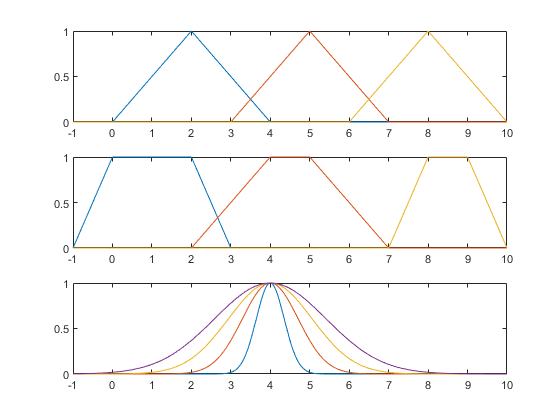

figure(1);
subplot(3,1,1);
fplot(triangleFunctions{1}, interval); hold on;
fplot(triangleFunctions{2}, interval);
fplot(triangleFunctions{3}, interval); hold off;

subplot(3,1,2);
fplot(trapezoidalFuctions{1}, interval); hold on;
fplot(trapezoidalFuctions{2}, interval);
fplot(trapezoidalFuctions{3}, interval); hold off;

subplot(3,1,3);
fplot(gaussianFunctions{1}, interval); hold on;
fplot(gaussianFunctions{2}, interval);
fplot(gaussianFunctions{3}, interval);
fplot(gaussianFunctions{4}, interval); hold off;

#### Plot Complement Functions

Realize the plot of last complement defined functions

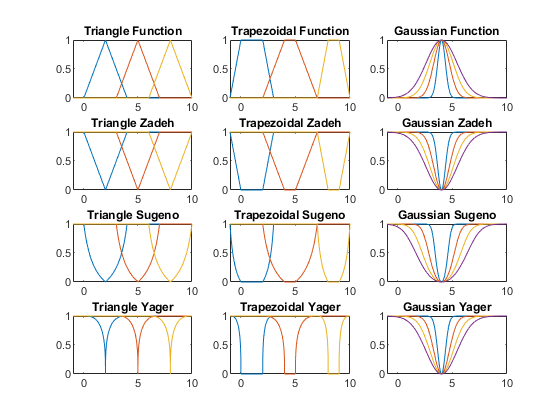

figure(2);
subplot(4,3,1);
fplot(triangleFunctions{1}, interval); hold on;
fplot(triangleFunctions{2}, interval);
fplot(triangleFunctions{3}, interval); hold off;
title("Triangle Function")
subplot(4,3,2);
fplot(trapezoidalFuctions{1}, interval); hold on;
fplot(trapezoidalFuctions{2}, interval);
fplot(trapezoidalFuctions{3}, interval); hold off;
title("Trapezoidal Function")
subplot(4,3,3);
fplot(gaussianFunctions{1}, interval); hold on;
fplot(gaussianFunctions{2}, interval);
fplot(gaussianFunctions{3}, interval);
fplot(gaussianFunctions{4}, interval); hold off;
title("Gaussian Function")

subplot(4,3,4);
fplot(@(x) zedehComplement(x,triangleFunctions{1}), interval); hold on;
fplot(@(x) zedehComplement(x,triangleFunctions{2}), interval); 
fplot(@(x) zedehComplement(x,triangleFunctions{3}), interval); hold off;
title("Triangle Zadeh");
subplot(4,3,5);
fplot(@(x) zedehComplement(x,trapezoidalFuctions{1}), interval); hold on;
fplot(@(x) zedehComplement(x,trapezoidalFuctions{2}), interval); 
fplot(@(x) zedehComplement(x,trapezoidalFuctions{3}), interval); hold off;
title("Trapezoidal Zadeh");
subplot(4,3,6);
fplot(@(x) zedehComplement(x,gaussianFunctions{1}), interval); hold on;
fplot(@(x) zedehComplement(x,gaussianFunctions{2}), interval); 
fplot(@(x) zedehComplement(x,gaussianFunctions{3}), interval); 
fplot(@(x) zedehComplement(x,gaussianFunctions{4}), interval); hold off;
title("Gaussian Zadeh");

subplot(4,3,7); s = 2;
fplot(@(x) sugenoComplement(x, s, triangleFunctions{1}), interval); hold on;
fplot(@(x) sugenoComplement(x, s, triangleFunctions{2}), interval); 
fplot(@(x) sugenoComplement(x, s, triangleFunctions{3}), interval); hold off;
title("Triangle Sugeno");
subplot(4,3,8);
fplot(@(x) sugenoComplement(x, s, trapezoidalFuctions{1}), interval); hold on;
fplot(@(x) sugenoComplement(x, s, trapezoidalFuctions{2}), interval); 
fplot(@(x) sugenoComplement(x, s, trapezoidalFuctions{3}), interval); hold off;
title("Trapezoidal Sugeno");
subplot(4,3,9);
fplot(@(x) sugenoComplement(x, s, gaussianFunctions{1}), interval); hold on;
fplot(@(x) sugenoComplement(x, s, gaussianFunctions{2}), interval); 
fplot(@(x) sugenoComplement(x, s, gaussianFunctions{3}), interval); 
fplot(@(x) sugenoComplement(x, s, gaussianFunctions{4}), interval); hold off;
title("Gaussian Sugeno");

subplot(4,3,10); w = 3;
fplot(@(x) yagerComplement(x, w, triangleFunctions{1}), interval); hold on;
fplot(@(x) yagerComplement(x, w, triangleFunctions{2}), interval); 
fplot(@(x) yagerComplement(x, w, triangleFunctions{3}), interval); hold off;
title("Triangle Yager");
subplot(4,3,11); w = 3;
fplot(@(x) yagerComplement(x, w, trapezoidalFuctions{1}), interval); hold on;
fplot(@(x) yagerComplement(x, w, trapezoidalFuctions{2}), interval); 
fplot(@(x) yagerComplement(x, w, trapezoidalFuctions{3}), interval); hold off;
title("Trapezoidal Yager");
subplot(4,3,12); w = 1;
fplot(@(x) yagerComplement(x, w, gaussianFunctions{1}), interval); hold on;
fplot(@(x) yagerComplement(x, w, gaussianFunctions{2}), interval); 
fplot(@(x) yagerComplement(x, w, gaussianFunctions{3}), interval); 
fplot(@(x) yagerComplement(x, w, gaussianFunctions{4}), interval); hold off;
title("Gaussian Yager");

#### Plot Functions Intersect

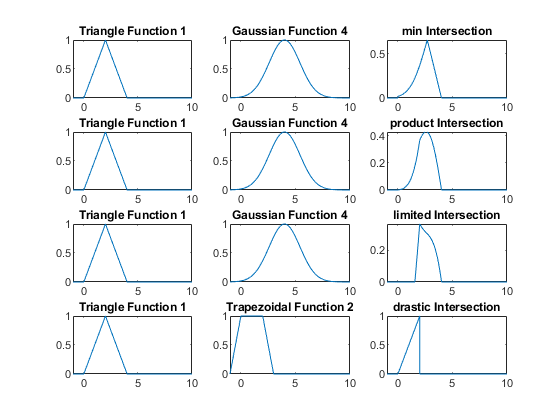

figure(3);
subplot(4,3,1);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,2);     fplot(gaussianFunctions{4}, interval);
title("Gaussian Function 4")
subplot(4,3,3);     fplot(@(x) minIntersection(x, triangleFunctions{1}, gaussianFunctions{4}), interval); 
title("min Intersection")

subplot(4,3,4);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,5);     fplot(gaussianFunctions{4}, interval);
title("Gaussian Function 4")
subplot(4,3,6);     fplot(@(x) productIntersection(x, triangleFunctions{1}, gaussianFunctions{4}), interval); 
title("product Intersection")

subplot(4,3,7);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,8);     fplot(gaussianFunctions{4}, interval);
title("Gaussian Function 4")
subplot(4,3,9);     fplot(@(x) limitedIntersection(x, triangleFunctions{1}, gaussianFunctions{4}), interval); 
title("limited Intersection")

subplot(4,3,10);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,11);     fplot(trapezoidalFuctions{1}, interval);
title("Trapezoidal Function 2")
subplot(4,3,12);     fplot(@(x) drasticIntersection(x, triangleFunctions{1}, trapezoidalFuctions{1}), interval); 
title("drastic Intersection")

#### Plot Union

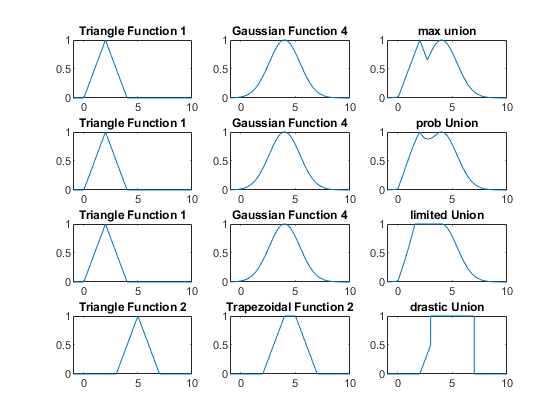

figure(4);
subplot(4,3,1);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,2);     fplot(gaussianFunctions{4}, interval);
title("Gaussian Function 4")
subplot(4,3,3);     fplot(@(x) maxUnion(x, triangleFunctions{1}, ...
    gaussianFunctions{4}), interval); 
title("max union")

subplot(4,3,4);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,5);     fplot(gaussianFunctions{4}, interval);
title("Gaussian Function 4")
subplot(4,3,6);     fplot(@(x) probUnion(x, triangleFunctions{1}, ...
    gaussianFunctions{4}), interval); 
title("prob Union")

subplot(4,3,7);     fplot(triangleFunctions{1}, interval); 
title("Triangle Function 1")
subplot(4,3,8);     fplot(gaussianFunctions{4}, interval);
title("Gaussian Function 4")
subplot(4,3,9);     fplot(@(x) limitedUnion(x, triangleFunctions{1}, ...
    gaussianFunctions{4}), interval); 
title("limited Union")

subplot(4,3,10);     fplot(triangleFunctions{2}, interval); 
title("Triangle Function 2")
subplot(4,3,11);     fplot(trapezoidalFuctions{2}, interval);
title("Trapezoidal Function 2")
subplot(4,3,12);     fplot(@(x) drasticUnion(x, triangleFunctions{2}, ...
    trapezoidalFuctions{2}), interval); 
title("drastic Union")

#### Funções de Pertinência

Definição da função triangular

function res = triangle(x,a,m,b)
res = max(min((x-a)/(m-a), (b-x)/(b-m)), 0);
end

Definição da função Trapezoidal

function res = trapezoidal(x,a,m,n,b)
a = min((x-a)./(m-a), (b-x)./(b-n));
res = max(min(a, 1), 0);
end

Definição da função Gaussiana

function res = gaussian(x, m, k)
k = k/2;
res = exp((-(x-m).^2)/(k^2));
end

#### Funções de União (S - normas)

Zadeh - max

function res = maxUnion(x, func1, func2)
    res = max(func1(x), func2(x));
end

Soma Probabilistica

function res = probUnion(x, func1, func2)
    res = func1(x) + func2(x) - func1(x).*func2(x);
end

Soma Limitada

function res = limitedUnion(x, func1, func2)
    res = min(1, func1(x) + func2(x));
end

Soma Drástica

function res = drasticUnion(x, func1, func2)
    if (func1(x) == 0)
        res = func2(x);
    elseif (func2(x) == 0)
        res = func1(x);
    else
        res = 1;
    end
end

#### Funçoes de Intercessão ( T - normas )

Zadeh - min

function res = minIntersection(x, func1, func2)
    res = min(func1(x), func2(x));
end

Algebraic product

function res = productIntersection(x, func1, func2)
    res = func1(x).*func2(x);
end

Limited difference

function res = limitedIntersection(x, func1, func2)
    res = max(0, func1(x) + func2(x) - 1);
end

Drastic product

function res = drasticIntersection(x, func1, func2)
    if (func1(x) == 1)
        res = func2(x);
    elseif (func2(x) == 1)
        res = func1(x);
    else
        res = 0;
    end
end

#### Funções de Complemento

Zadeh - probabilistic complement

function res = zedehComplement(x, func)
    res = 1 - func(x);
end

Sugeno | s pertence (-1, infinito)

function res = sugenoComplement(x, s, func)
    if s >= -1; s = s; else; s = -1; end
    res = (1-func(x)) ./ (1+s*func(x));
end

Yager

function res = yagerComplement(x, w, func)
    res = (1-func(x).^w).^(1./w);
end